Workflow Oxcart mass spectrum calibration

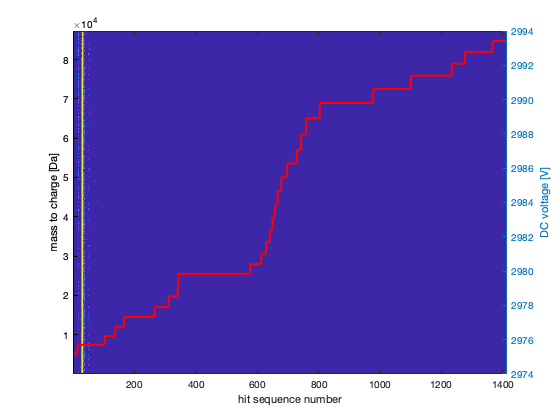

mc = tof2mcSimple(pos.tof,0,pos.VDC,pos.detx,pos.dety,110);


%plotting data history
historyFig = figure("Name","mc experiment history");
historyAx = axes(historyFig);
MAXMC = 100; %maximum time of flight that makes sense
HISTORYPIX = 1024; %number of pixels in the hit sequence tof image
TOFPIX = 512; % number of vertical pixels for tof image

numAtom = length(mc);

[mcImage, tofImageCenters] = hist3([mc, (1:length(mc))'],[HISTORYPIX,TOFPIX]);
mcImage = mcImage';
mcImage = log(mcImage); % if weak peaks are to be imaged
im = imagesc(mcImage,'XData',tofImageCenters{1},'YData',tofImageCenters{2});
historyAx.YDir = "normal";

% plotting voltage history
yyaxis right
p = plot(pos.VDC,'r');
p.LineWidth = 2;
ylabel 'DC voltage [V]'

% image formatting
yyaxis left
ylabel 'mass to charge [Da]'
xlabel 'hit sequence number'

peak tracking - simple voltage

fitPeaks = [16.7, 18; 30, 31.4] % peaks as beginning/end

fitPeaks =    16.7000   18.0000
   30.0000   31.4000


ionsPerFitSegment = 10000;
numMcBins = round(numAtom/ionsPerFitSegment);
binLimits = round(linspace(1,numAtom,numMcBins+1));
binCenters = round((binLimits(2:end) + binLimits(1:end-1))/2)

binCenters =         5241       15721       26201       36681       47161       57641       68121       78601


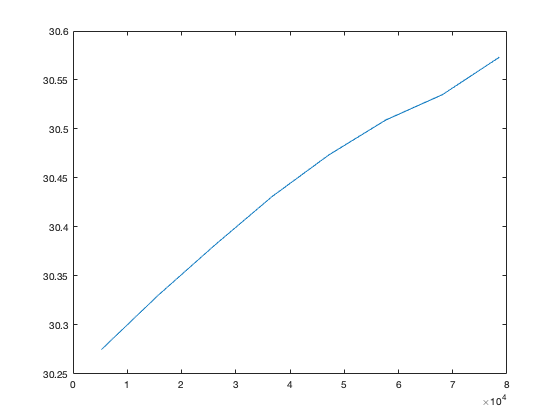


for i = 1:numMcBins
    mcBin = mc(binLimits(i):binLimits(i+1));
    mcBin = mcBin(mcBin>fitPeaks(2,1) & mcBin<fitPeaks(2,2));
    pkLoc(i) = median(mcBin);
    
end
figure;
plot(binCenters,pkLoc);

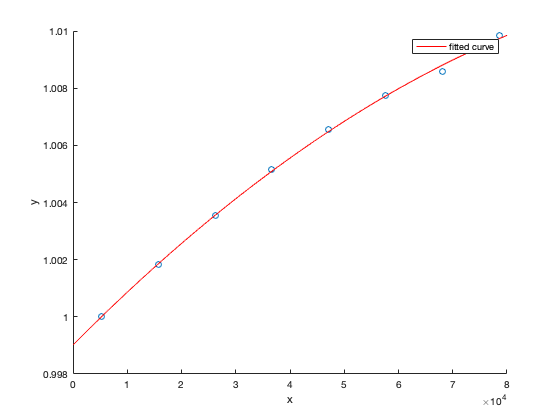



corr = pkLoc/pkLoc(1);

figure
scatter(binCenters, corr)
hold on

[xData, yData] = prepareCurveData( binCenters, corr );
% Set up fittype and options.
ft = fittype( 'poly2' );
% Fit model to data.
fitresult = fit( xData, yData, ft );
plot(fitresult);

%
%corrFac = interp1(binCenters,corr,1:length(mc),'linear','extrap')';
corrFac = fitresult(mc);
mc2 = mc ./ corrFac;

clear corr corrFac

single bowl fit

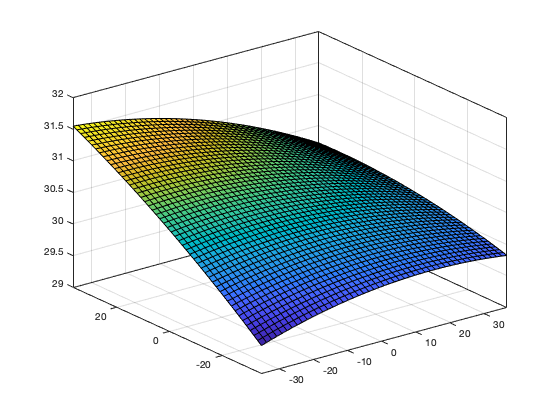

%bowl fit on full data
in = mc>fitPeaks(2,1) & mc<fitPeaks(2,2);
detxIn = pos.detx(in);
detyIn = pos.dety(in);
mcIn = mc(in);

[xData, yData, zData] = prepareSurfaceData( detxIn, detyIn, mcIn );
ft = fittype( 'poly22' );
[bowlFit, gof] = fit( [xData, yData], zData, ft );

figure( 'Name', 'Bowl fit 1' );
h = plot(bowlFit);


corr = bowlFit(pos.detx,pos.dety)/bowlFit(0,0);

mc3 = mc ./ corr;

fitPeaks =    16.7000   18.0000
   31.1000   33.2300


binCenters =        51343      154026      256709      359392      462075      564758      667441      770124      872807      975491     1078174     1180857     1283540     1386223     1488906     1591589     1694272


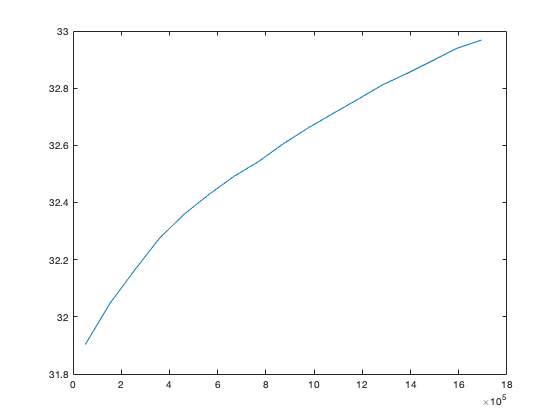

iterative fitting of peak to voltage curve 